# Sprawozdanie Rozwiązywanie Równań Nieliniowych

Tomasz Kowalski 313565

clc
clear
close all


_____________________________

#### Prezentacja algorytmu bisekcji.

a = 3;
b = 4;
eps = 10^(-5);

fun1 = @(x) sin(x);
fun2 = @(x) x - 3.333;       %3 liczby po przecinku
fun3 = @(x) x - 3.333333;    %6 liczb po przecinku
fun4 = @(x) x^2 - 13;

wyniki = zeros(3,4);

wyniki(1,1) = pi;
wyniki(1,2) = 3.333;
wyniki(1,3) = 3.333333;
wyniki(1,4) = sqrt(13);

wyniki(2,1) = bisek( a, b, fun1,  eps);
wyniki(2,2) = bisek( a, b, fun2,  eps);
wyniki(2,3) = bisek( a, b, fun3,  eps);
wyniki(2,4) = bisek( a, b, fun4,  eps);

wyniki(3,1) = abs(wyniki(1,1)-wyniki(2,1));
wyniki(3,2) = abs(wyniki(1,2)-wyniki(2,2));
wyniki(3,3) = abs(wyniki(1,3)-wyniki(2,3));
wyniki(3,4) = abs(wyniki(1,4)-wyniki(2,4));

format longG
disp(wyniki)

          3.14159265358979                     3.333                  3.333333          3.60555127546399
          3.14159393310547          3.33300018310547          3.33333587646484          3.60555267333984
        1.279515675634e-06      1.83105468565259e-07      2.87646484364856e-06      1.39787585462514e-06



#### _____________________________________________

#### Prezantacja algorytmu biskecji ze złotym podziałem.

a = 3;
b = 4;
eps = 10^(-5);

fun1 = @(x) sin(x);
fun2 = @(x) x - 3.333;       %3 liczby po przecinku
fun3 = @(x) x - 3.333333;    %6 liczb po przecinku
fun4 = @(x) x^2 - 13;

wyniki = zeros(3,4);

wyniki(1,1) = pi;
wyniki(1,2) = 3.333;
wyniki(1,3) = 3.333333;
wyniki(1,4) = sqrt(13);

wyniki(2,1) = bisekZP( a, b, fun1,  eps);
wyniki(2,2) = bisekZP( a, b, fun2,  eps);
wyniki(2,3) = bisekZP( a, b, fun3,  eps);
wyniki(2,4) = bisekZP( a, b, fun4,  eps);

wyniki(3,1) = abs(wyniki(1,1)-wyniki(2,1));
wyniki(3,2) = abs(wyniki(1,2)-wyniki(2,2));
wyniki(3,3) = abs(wyniki(1,3)-wyniki(2,3));
wyniki(3,4) = abs(wyniki(1,4)-wyniki(2,4));

format longG
disp(wyniki)

          3.14159265358979                     3.333                  3.333333          3.60555127546399
          3.14160021158454          3.33300326758271          3.33333976325045          3.60555504660365
      7.55799475138375e-06      3.26758270574601e-06      6.76325045168014e-06      3.77113966454345e-06



#### ________________________________________________________________

#### Prezentacja algorytmu Newtona-Raphsona z podanym wzorem pochodnej.

a = 3;
b = 4;
x1 = 3.3

x1 =                        3.3


eps = 10^(-5);

fun1 = @(x) sin(x);
fun1p = @(x) cos(x);
fun2 = @(x) x - 3.333;       %3 liczby po przecinku
fun3 = @(x) x - 3.333333;    %6 liczb po przecinku
fun23p = @(x) 1;
fun4 = @(x) x^2 - 13;
fun4p = @(x) 2*x;

wyniki = zeros(3,4);

wyniki(1,1) = pi;
wyniki(1,2) = 3.333;
wyniki(1,3) = 3.333333;
wyniki(1,4) = sqrt(13);

wyniki(2,1) = NewtonRaphson( a, b, x1, fun1, fun1p,  eps);
wyniki(2,2) = NewtonRaphson( a, b, x1, fun2, fun23p,  eps);
wyniki(2,3) = NewtonRaphson( a, b, x1, fun3, fun23p,  eps);
wyniki(2,4) = NewtonRaphson( a, b, x1, fun4, fun4p,  eps);

wyniki(3,1) = abs(wyniki(1,1)-wyniki(2,1));
wyniki(3,2) = abs(wyniki(1,2)-wyniki(2,2));
wyniki(3,3) = abs(wyniki(1,3)-wyniki(2,3));
wyniki(3,4) = abs(wyniki(1,4)-wyniki(2,4));

format longG
disp(wyniki)

          3.14159265358979                     3.333                  3.333333          3.60555127546399
          3.14159265358979                     3.333                  3.333333          3.60555127546399
                         0                         0                         0      4.44089209850063e-16



#### ___________________________________________________________

#### Prezentacja algorytmu Newtona-Raphsona z obliczeniem pochodnej.

a = 3;
b = 4;
x1 = 3.3

x1 =                        3.3


h = 10^(-5);
eps = 10^(-5);

fun1 = @(x) sin(x);
fun1p = @(x) cos(x);
fun2 = @(x) x - 3.333;       %3 liczby po przecinku
fun3 = @(x) x - 3.333333;    %6 liczb po przecinku
fun23p = @(x) 1;
fun4 = @(x) x^2 - 13;
fun4p = @(x) 2*x;

wyniki = zeros(3,4);

wyniki(1,1) = pi;
wyniki(1,2) = 3.333;
wyniki(1,3) = 3.333333;
wyniki(1,4) = sqrt(13);

wyniki(2,1) = NewtonRaphsonOblP( a, b, x1, fun1, fun1p,  eps, h);
wyniki(2,2) = NewtonRaphsonOblP( a, b, x1, fun2, fun23p,  eps, h);
wyniki(2,3) = NewtonRaphsonOblP( a, b, x1, fun3, fun23p,  eps, h);
wyniki(2,4) = NewtonRaphsonOblP( a, b, x1, fun4, fun4p,  eps, h);

wyniki(3,1) = abs(wyniki(1,1)-wyniki(2,1));
wyniki(3,2) = abs(wyniki(1,2)-wyniki(2,2));
wyniki(3,3) = abs(wyniki(1,3)-wyniki(2,3));
wyniki(3,4) = abs(wyniki(1,4)-wyniki(2,4));

format longG
disp(wyniki)

          3.14159265358979                     3.333                  3.333333          3.60555127546399
          3.14159265358979                     3.333                  3.333333          3.60555127546399
                         0                         0                         0      4.44089209850063e-16



#### __________________________________________________________________________________________________

#### Porównanie zbieżności metody bisekcji w oparciu o równomierny podział, z metodą bisekcji opartą o złoty podział.

eps1 = 10^(-5);
eps2 = 10^(-9);
eps3 = 10^(-12);

a = 3;
b = 4;

fun = @(x) x*sin(x);

wyniki = zeros(2,3);
tmp = zeros(3,3);

[tmp(1,1),wyniki(1,1)] = bisek( a, b, fun,  eps1);
[tmp(2,1),wyniki(2,1)] = bisekZP( a, b, fun,  eps1);
[tmp(1,2),wyniki(1,2)] = bisek( a, b, fun,  eps2);
[tmp(2,2),wyniki(2,2)] = bisekZP( a, b, fun,  eps2);
[tmp(1,3),wyniki(1,3)] = bisek( a, b, fun,  eps3);
[tmp(2,3),wyniki(2,3)] = bisekZP( a, b, fun,  eps3);

tmp(3,1) = abs(tmp(1,1)-tmp(2,1));
tmp(3,2) = abs(tmp(1,2)-tmp(2,2));
tmp(3,3) = abs(tmp(1,3)-tmp(2,3));

dane = wyniki;

nowe_dane = [dane(1, :); dane(2, :)]';
bar(nowe_dane)
xticks(1:size(nowe_dane, 1))
xticklabels({'-5', '-9', '-12'})
xlabel('dokładność 10 do potęgi')
ylabel('Ilość iteracji')
lgd = legend('bisekcja', 'bisekcja ze złotym podziałem')

lgd =   Legend (bisekcja, bisekcja ze złotym podziałem) with properties:

         String: {'bisekcja'  'bisekcja ze złotym podziałem'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.526429786270991 0.825635103926097 0.359185441941074 0.0750577367205543]
          Units: 'normalized'

  Show all properties


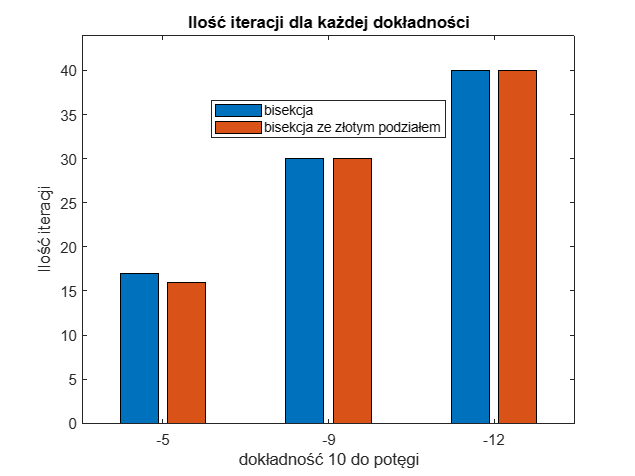

set(lgd, 'Location', 'best')
title('Ilość iteracji dla każdej dokładności')
ylim([0 max(nowe_dane(:))*1.1])

dane

dane =     17    30    40
    16    30    40


**Obie metody bisekcji są zbierze ze sobą. Możemy zauważyć że wyniki sa dość podobne. Jednak specjalnie wybrałem taką funkcję aby móc sprawdzić inne jej miejsca zerowe.**

**Dla przedziału< 3 ; 4 > oraz < 6 ; 7 > również wyniki są podobne do siebie. Jednak dla przedziału < 9 ; 10 > wyniki dą na kożyść normalnej bisekcji.**

**Wszystko zależy od miejsca zerowego które liczymy wtedy jedne metody mogą sprawdzić się lepiej a inne gorzej.**

#### **___________________________________________________**

#### Porównanie metodę bisekcji z metodą Newtona –Raphsona.

eps1 = 10^(-5);
eps2 = 10^(-9);
eps3 = 10^(-12);

wsp = 0.8;

a = 3;
b = 4;
x1 = a+0.3;

fun = @(x) wsp*x*sin(x);
funP = @(x) wsp*(sin(x) + x*cos(x));

wyniki = zeros(2,3);
tmp = zeros(2,3);

tic;
[tmp(1,1),wyniki(1,1)] = bisek( a, b, fun,  eps1);
wyniki(1,1) = toc;
tic;
[tmp(1,1),wyniki(1,2)] = bisek( a, b, fun,  eps2);
wyniki(1,2) = toc;
tic;
[tmp(1,1),wyniki(1,3)] = bisek( a, b, fun,  eps3);
wyniki(1,3) = toc;


tic;
[tmp(2,1),wyniki(2,1)] = NewtonRaphson( a, b, x1,  fun, funP,  eps1);
wyniki(2,1) = toc;
tic;
[tmp(2,1),wyniki(2,2)] = NewtonRaphson( a, b, x1,  fun, funP,  eps2);
wyniki(2,2) = toc;
tic;
[tmp(2,1),wyniki(2,3)] = NewtonRaphson( a, b, x1,  fun, funP,  eps3);
wyniki(2,3) = toc;

dane = wyniki;

nowe_dane = [dane(1, :); dane(2, :)]';
bar(nowe_dane)
xticks(1:size(nowe_dane, 1))
xticklabels({'-5', '-9', '-12'})
xlabel('dokładność 10 do potęgi')
ylabel('czas działania')
lgd = legend('bisekcja', 'Newton-Raphson')

lgd =   Legend (bisekcja, Newton-Raphson) with properties:

         String: {'bisekcja'  'Newton-Raphson'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.633882125959033 0.825635142648038 0.251733102253033 0.0750577367205543]
          Units: 'normalized'

  Show all properties


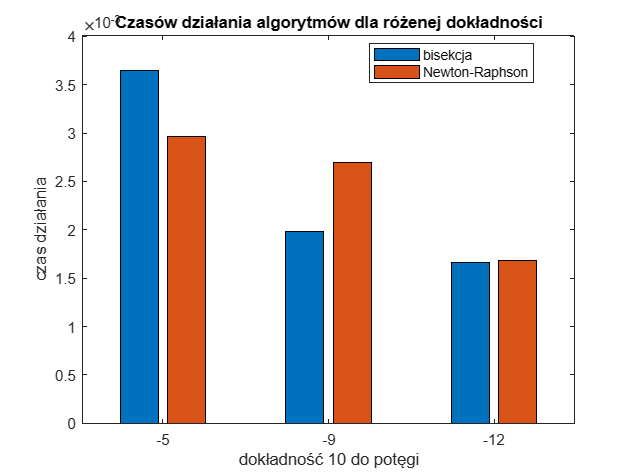

set(lgd, 'Location', 'best')
title('Czasów działania algorytmów dla różenej dokładności')
ylim([0 max(nowe_dane(:))*1.1])

dane

dane =                   0.003647                  0.001984                  0.001657
                  0.002966                  0.002691                  0.001679


**Ciężko określić który algorytm radzi sobie lepiej. Funkcja tik tok nie jest idealna a wszysko zależy również od spżętku na którym pracujemy. Dodłam współczynink zmieny okresu funkcji ale nadal wyniki są zadziwiające bo algorytmy szybciej radzą sobie ze znalezieniem dokładniejszych wyników niż tych mniej dokładnych.**

Implementacja algorytmu bisekcji

function [x,i] = bisek(a, b, fun, eps)
    i=0;
    x=0;
    while(abs(a-b) > eps)

        x = (a + b) / 2;
        if fun(x) * fun(a) < 0
            b = x;
        else
            a = x;
        end
        i=i+1;
    end
    i;
end

Implementacja algorytmu bisekcji ze złotym podziałem.

function [x,i] = bisekZP(a, b, fun, eps)
    i=0;
    x=0;
    while(abs(a-b) > eps)

        x = zlatyPodzial(a,b);
        if fun(x) * fun(a) < 0
            b = x;
        else
            a = x;
        end
        i=i+1;
    end
end

function x = zlatyPodzial(a,b)
    rho = (sqrt(5) + 1)/2;
    x = (b-a)/rho;
    x=x+a;
end

Implementacja algorytmu Newtona-Raphsona z podanym wzorrem pochodnej.

function [x,i] = NewtonRaphson (a, b, x, fun, funP, eps)
    if x == 1
        r = 2;
    else
        r = 1;
    end
    i = 0;
    while(abs(r-x)>eps)
        r = x;
        x = x - (fun(x)/funP(x));
        i = i + 1;
    end
    i;
end

Implementacja algorytmu Newtona-Raphsona z obliczeniem pochodnej.

function [x,i] = NewtonRaphsonOblP (a, b, x, fun, funP, eps, h)
    if x == 1
        r = 2;
    else
        r = 1;
    end
    i = 0;
    while(abs(r-x)>eps)
        r = x;
        x = x - (fun(x)/pochodnaWPkt(x, fun, h));
        i = i + 1;
    end
    i;
end

function fx = pochodnaWPkt (x, fun, h)
    fx  = (fun(x+h) - fun(x))/h;
end